# Modelo robot movil

## Constantes

syms a b theta xp yp tp r t 

%medidas
a = 11.78/2;
b = 9.13/2;
r = 1.19;
%Tiempo en el que se llegara al lugar [s]
T = 10;
%Posiciones en cm
xi = 0;%x inicial
yi = 0;%y inicial
xf = 100;%x final
yf = 100;%y final
d = sqrt((xf-xi)^2+(yf-yi)^2);
v = d/T;%cm/s
psi = atan2(yf-yi,xf-xi);
%Angulos en rad
ti = 0;%theta inicial
tf = pi;%theta final

%velocidades del robot
xp = v*sin(psi)

xp = 10

yp = v*cos(psi)

yp = 10.0000

tp = pi/T;%rad/s


theta = tp*t %El angulo dependera del tiempo

$$theta = \frac{\pi \,t}{10}$$


RZ = [cos(theta),-sin(theta),0;sin(theta),cos(theta),0;0,0,1]

$$RZ = \left(\begin{array}{ccc} \cos\left(\frac{\pi \,t}{10}\right) & -\sin\left(\frac{\pi \,t}{10}\right) & 0\\ \sin\left(\frac{\pi \,t}{10}\right) & \cos\left(\frac{\pi \,t}{10}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

EI = [xp;yp;tp]

EI =    10.0000
   10.0000
    0.3142


ER = RZ^(-1)*EI

$$ER = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}+\sigma_{2}\\ \sigma_{1}-\sigma_{2}\\ \frac{\pi }{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{10\,\cos\left(\frac{\pi \,t}{10}\right)}{{\cos\left(\frac{\pi \,t}{10}\right)}^{2}+{\sin\left(\frac{\pi \,t}{10}\right)}^{2}}\\ \sigma_{2}=\frac{10\,\sin\left(\frac{\pi \,t}{10}\right)}{{\cos\left(\frac{\pi \,t}{10}\right)}^{2}+{\sin\left(\frac{\pi \,t}{10}\right)}^{2}} \end{array}$$

%set L
L = sqrt(a*a+b*b)

L = 7.4519

%Set alphas
alpha1 = atan(b/a)

alpha1 = 0.6593

alpha2 = pi-alpha1

alpha2 = 2.4823

alpha3 = pi+alpha1

alpha3 = 3.8009

alpha4 = 2*pi-alpha1

alpha4 = 5.6238

alpha = [alpha1;alpha2;alpha3;alpha4]

alpha =     0.6593
    2.4823
    3.8009
    5.6238


%Set betas
%90 - alpha + angulodeU1

beta2 = pi/2-alpha2 

beta2 = -0.9115

beta3 = pi/2-alpha3

beta3 = -2.2301

beta4 = pi/2-alpha4

beta4 = -4.0531

beta = [beta1;beta2;beta3;beta4]

beta =     0.9115
   -0.9115
   -2.2301
   -4.0531


J = [sin(alpha+beta),-cos(alpha+beta),-L*cos(beta)];
J(abs(J)<1e-3)=0

J =     1.0000         0   -4.5650
    1.0000         0   -4.5650
    1.0000         0    4.5650
    1.0000         0    4.5650


C=[cos(alpha+beta), sin(alpha+beta), L*sin(beta)]

C =     0.0000    1.0000    5.8900
    0.0000    1.0000   -5.8900
    0.0000    1.0000   -5.8900
    0.0000    1.0000    5.8900


J2 = r*eye(4)

J2 =     1.1900         0         0         0
         0    1.1900         0         0
         0         0    1.1900         0
         0         0         0    1.1900


C(1,:)*ER==0

$$ans = \frac{589\,\pi }{1000}+\frac{405648192073033433317733025827875\,\cos\left(\frac{\pi \,t}{10}\right)}{40564819207303340847894502572032\,\left({\cos\left(\frac{\pi \,t}{10}\right)}^{2}+{\sin\left(\frac{\pi \,t}{10}\right)}^{2}\right)}-\frac{405648192073033383640157025612765\,\sin\left(\frac{\pi \,t}{10}\right)}{40564819207303340847894502572032\,\left({\cos\left(\frac{\pi \,t}{10}\right)}^{2}+{\sin\left(\frac{\pi \,t}{10}\right)}^{2}\right)}=0$$

A = [J(1,:);J(3,:);C(1,:)]

A =     1.0000         0   -4.5650
    1.0000         0    4.5650
    0.0000    1.0000    5.8900



phip = J*ER/r;
phip = vpa(simplify(phip),3)

$$phip = \left(\begin{array}{c} 11.9\,\sin\left(0.314\,t+0.785\right)-1.21\\ 11.9\,\sin\left(0.314\,t+0.785\right)-1.21\\ 11.9\,\sin\left(0.314\,t+0.785\right)+1.21\\ 11.9\,\sin\left(0.314\,t+0.785\right)+1.21 \end{array}\right)$$

syms t
R = (r/2)*eye(3)

R =     0.5950         0         0
         0    0.5950         0
         0         0    0.5950


A = R*[cos(theta) cos(theta);sin(theta) sin(theta);1/b -1/b]

$$A = \left(\begin{array}{cc} \frac{119\,\cos\left(\frac{\pi \,t}{10}\right)}{200} & \frac{119\,\cos\left(\frac{\pi \,t}{10}\right)}{200}\\ \frac{119\,\sin\left(\frac{\pi \,t}{10}\right)}{200} & \frac{119\,\sin\left(\frac{\pi \,t}{10}\right)}{200}\\ \frac{119}{913} & -\frac{119}{913} \end{array}\right)$$

phip = pinv(A)*EI;
phi = vpa(phip*t,3);
t = 0:0.1:T

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


pos = vpa(eval(A*phi),3)

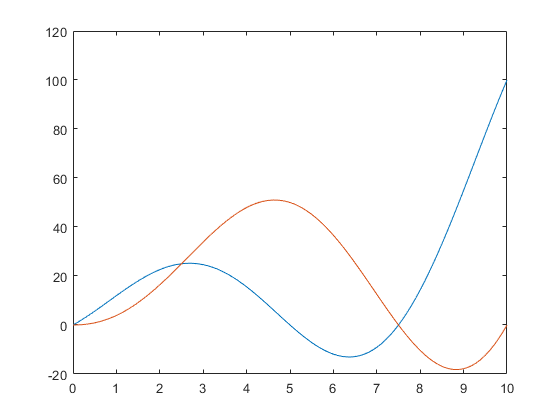

plot(t,pos(1,:))
hold on
plot(t,pos(2,:))
hold off

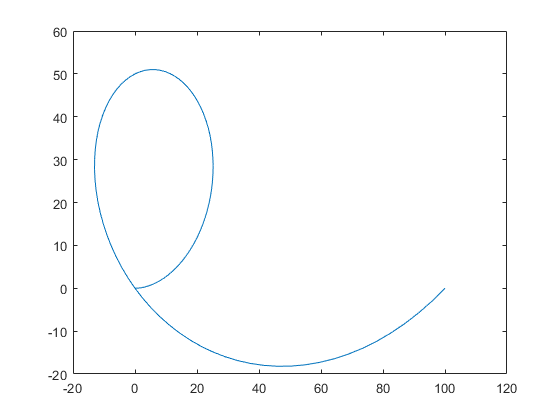

plot(pos(1,:),pos(2,:))

syms t
VR = vpa(sum(phip*r)/2,3)

$$VR = \begin{array}{l} \frac{0.0244}{\sigma_{6}}-\frac{0.187\,\sigma_{2}}{\sigma_{1}}+\frac{5.95\,\sigma_{4}}{\sigma_{1}}+\frac{5.95\,\sigma_{3}}{\sigma_{1}}+\frac{3.54\,\cos\left(0.314\,\bar{t}\right)}{\sigma_{6}}+\frac{3.54\,\sin\left(0.314\,\bar{t}\right)}{\sigma_{6}}+\frac{0.187\,\sigma_{5}\,\sigma_{2}}{\sigma_{1}}-\frac{5.95\,\sigma_{4}\,\sigma_{5}}{\sigma_{1}}-\frac{5.95\,\sigma_{3}\,\sigma_{5}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sigma_{4}\,\left(0.595\,\cos\left(0.314\,t\right)-0.595\,\cos\left(0.314\,t\right)\,\sigma_{5}\right)+{\sigma_{2}}^{2}+\sigma_{3}\,\left(0.595\,\sin\left(0.314\,t\right)-0.595\,\sin\left(0.314\,t\right)\,\sigma_{5}\right)\\ \sigma_{2}=\frac{0.0461\,\cos\left(0.314\,t\right)\,\cos\left(0.314\,\bar{t}\right)}{\sigma_{6}}-\frac{0.00221}{\sigma_{6}}+\frac{0.0461\,\sin\left(0.314\,t\right)\,\sin\left(0.314\,\bar{t}\right)}{\sigma_{6}}+0.13\\ \sigma_{3}=0.595\,\sin\left(0.314\,\bar{t}\right)-0.595\,\sin\left(0.314\,\bar{t}\right)\,\sigma_{5}\\ \sigma_{4}=0.595\,\cos\left(0.314\,\bar{t}\right)-0.595\,\cos\left(0.314\,\bar{t}\right)\,\sigma_{5}\\ \sigma_{5}=\frac{0.354\,\cos\left(0.314\,t\right)\,\cos\left(0.314\,\bar{t}\right)}{\sigma_{6}}-\frac{0.017}{\sigma_{6}}+\frac{0.354\,\sin\left(0.314\,t\right)\,\sin\left(0.314\,\bar{t}\right)}{\sigma_{6}}\\ \sigma_{6}=0.354\,\cos\left(0.314\,t\right)\,\cos\left(0.314\,\bar{t}\right)+0.354\,\sin\left(0.314\,t\right)\,\sin\left(0.314\,\bar{t}\right)+0.017 \end{array}$$


X = vpa(VR*t*cos(theta),3)

$$X = \begin{array}{l} t\,\cos\left(0.314\,t\right)\,\left(\frac{0.0244}{\sigma_{6}}-\frac{0.187\,\sigma_{2}}{\sigma_{1}}+\frac{5.95\,\sigma_{4}}{\sigma_{1}}+\frac{5.95\,\sigma_{3}}{\sigma_{1}}+\frac{3.54\,\cos\left(0.314\,\bar{t}\right)}{\sigma_{6}}+\frac{3.54\,\sin\left(0.314\,\bar{t}\right)}{\sigma_{6}}+\frac{0.187\,\sigma_{5}\,\sigma_{2}}{\sigma_{1}}-\frac{5.95\,\sigma_{4}\,\sigma_{5}}{\sigma_{1}}-\frac{5.95\,\sigma_{3}\,\sigma_{5}}{\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{4}\,\left(0.595\,\cos\left(0.314\,t\right)-0.595\,\cos\left(0.314\,t\right)\,\sigma_{5}\right)+{\sigma_{2}}^{2}+\sigma_{3}\,\left(0.595\,\sin\left(0.314\,t\right)-0.595\,\sin\left(0.314\,t\right)\,\sigma_{5}\right)\\ \sigma_{2}=\frac{0.0461\,\cos\left(0.314\,t\right)\,\cos\left(0.314\,\bar{t}\right)}{\sigma_{6}}-\frac{0.00221}{\sigma_{6}}+\frac{0.0461\,\sin\left(0.314\,t\right)\,\sin\left(0.314\,\bar{t}\right)}{\sigma_{6}}+0.13\\ \sigma_{3}=0.595\,\sin\left(0.314\,\bar{t}\right)-0.595\,\sin\left(0.314\,\bar{t}\right)\,\sigma_{5}\\ \sigma_{4}=0.595\,\cos\left(0.314\,\bar{t}\right)-0.595\,\cos\left(0.314\,\bar{t}\right)\,\sigma_{5}\\ \sigma_{5}=\frac{0.354\,\cos\left(0.314\,t\right)\,\cos\left(0.314\,\bar{t}\right)}{\sigma_{6}}-\frac{0.017}{\sigma_{6}}+\frac{0.354\,\sin\left(0.314\,t\right)\,\sin\left(0.314\,\bar{t}\right)}{\sigma_{6}}\\ \sigma_{6}=0.354\,\cos\left(0.314\,t\right)\,\cos\left(0.314\,\bar{t}\right)+0.354\,\sin\left(0.314\,t\right)\,\sin\left(0.314\,\bar{t}\right)+0.017 \end{array}$$

Y = vpa(VR*t*sin(theta),3)

$$Y = \begin{array}{l} t\,\sin\left(0.314\,t\right)\,\left(\frac{0.0244}{\sigma_{6}}-\frac{0.187\,\sigma_{2}}{\sigma_{1}}+\frac{5.95\,\sigma_{4}}{\sigma_{1}}+\frac{5.95\,\sigma_{3}}{\sigma_{1}}+\frac{3.54\,\cos\left(0.314\,\bar{t}\right)}{\sigma_{6}}+\frac{3.54\,\sin\left(0.314\,\bar{t}\right)}{\sigma_{6}}+\frac{0.187\,\sigma_{5}\,\sigma_{2}}{\sigma_{1}}-\frac{5.95\,\sigma_{4}\,\sigma_{5}}{\sigma_{1}}-\frac{5.95\,\sigma_{3}\,\sigma_{5}}{\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{4}\,\left(0.595\,\cos\left(0.314\,t\right)-0.595\,\cos\left(0.314\,t\right)\,\sigma_{5}\right)+{\sigma_{2}}^{2}+\sigma_{3}\,\left(0.595\,\sin\left(0.314\,t\right)-0.595\,\sin\left(0.314\,t\right)\,\sigma_{5}\right)\\ \sigma_{2}=\frac{0.0461\,\cos\left(0.314\,t\right)\,\cos\left(0.314\,\bar{t}\right)}{\sigma_{6}}-\frac{0.00221}{\sigma_{6}}+\frac{0.0461\,\sin\left(0.314\,t\right)\,\sin\left(0.314\,\bar{t}\right)}{\sigma_{6}}+0.13\\ \sigma_{3}=0.595\,\sin\left(0.314\,\bar{t}\right)-0.595\,\sin\left(0.314\,\bar{t}\right)\,\sigma_{5}\\ \sigma_{4}=0.595\,\cos\left(0.314\,\bar{t}\right)-0.595\,\cos\left(0.314\,\bar{t}\right)\,\sigma_{5}\\ \sigma_{5}=\frac{0.354\,\cos\left(0.314\,t\right)\,\cos\left(0.314\,\bar{t}\right)}{\sigma_{6}}-\frac{0.017}{\sigma_{6}}+\frac{0.354\,\sin\left(0.314\,t\right)\,\sin\left(0.314\,\bar{t}\right)}{\sigma_{6}}\\ \sigma_{6}=0.354\,\cos\left(0.314\,t\right)\,\cos\left(0.314\,\bar{t}\right)+0.354\,\sin\left(0.314\,t\right)\,\sin\left(0.314\,\bar{t}\right)+0.017 \end{array}$$

t = 0:0.1:T

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


X = eval(X)

X =          0    1.0306    2.1178    3.2550    4.4352    5.6509    6.8946    8.1582    9.4335   10.7122   11.9858   13.2458   14.4836   15.6908   16.8590   17.9800   19.0459   20.0489   20.9817   21.8372   22.6089   23.2906   23.8768   24.3623   24.7428   25.0145   25.1740   25.2191   25.1478   24.9592   24.6531   24.2298   23.6907   23.0378   22.2739   21.4027   20.4283   19.3561   18.1918   16.9419   15.6138   14.2152   12.7548   11.2417    9.6854    8.0962    6.4847    4.8618    3.2389    1.6276


Y = eval(Y)

Y =          0    0.0324    0.1332    0.3075    0.5600    0.8946    1.3145    1.8226    2.4208    3.1105    3.8923    4.7662    5.7313    6.7862    7.9287    9.1559   10.4643   11.8496   13.3070   14.8309   16.4153   18.0536   19.7385   21.4624   23.2173   24.9945   26.7854   28.5806   30.3709   32.1466   33.8980   35.6153   37.2886   38.9081   40.4642   41.9473   43.3479   44.6571   45.8660   46.9664   47.9503   48.8102   49.5392   50.1311   50.5802   50.8814   51.0306   51.0243   50.8596   50.5348


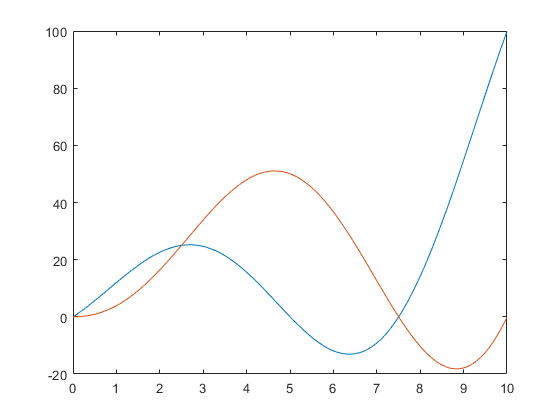

plot(t,X)
hold on
plot(t,Y)
hold off

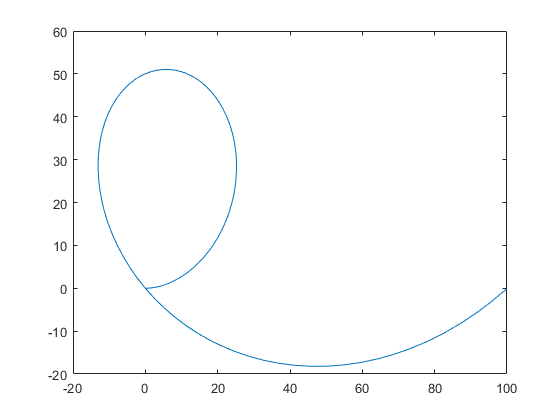

plot(X,Y)

% EI2 = EI*t;
% 
% 
% plot(t,EI2())
% hold on
% % plot(eval(phip(3)*r*t))
% hold off